clear all;
clc;
close all;

i=sqrt(-1); % imaginary unit
rng(123) % set constant seed
addpath('/home/john/Desktop/kspace-simulator/functions') % my functions
addpath('/home/john/mymatlab/finufft/matlab') % finufft libraries
addpath('/home/john/Desktop/Data/')

Test function. TR and TE taken from "Incorporating relaxivities..."

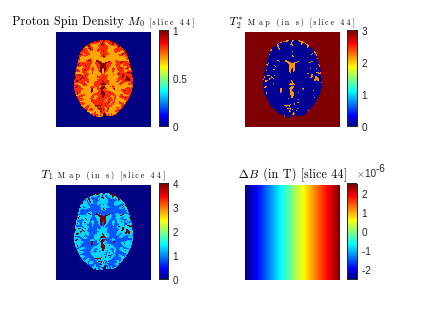

load SpinDenMap.mat
load T1Map.mat
load T2Map.mat

slice = 44;
rec_size = length(SpinDenMap);

M0=SpinDenMap(:,:,slice);
t2star=T2Map(:,:,slice);
t1=T1Map(:,:,slice);
deltaB = repmat(linspace(-2.5,2.5,rec_size)*10e-7,rec_size,1);

figure;
subplot(2,2,1)
imagesc(abs(M0), [0 1])
axis image; axis off;
colormap('gray'); colorbar;
title(['Proton Spin Density $M_0$ [slice ', num2str(slice),']'],Interpreter='latex')
subplot(2,2,2)
imagesc(abs(t2star),[0 3])
axis image; axis off;
colormap('jet'); colorbar;
title(['$T_2^*$ Map (in s) [slice ', num2str(slice),']'],Interpreter='latex')

subplot(2,2,3)
imagesc(abs(t1), [0 4])
axis image; axis off;
colormap('jet'); colorbar;
title(['$T_1$ Map (in s) [slice ', num2str(slice),']'],Interpreter='latex')
subplot(2,2,4)
imagesc(deltaB)
axis image; axis off;
colormap('jet'); colorbar;
title(['$\Delta B$ (in T) [slice ', num2str(slice),']'],Interpreter='latex')

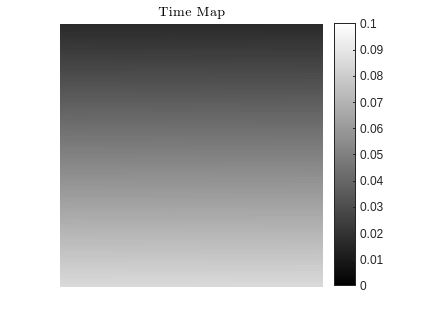




% create time map
eesp = 0.000720;
deltaT = 1/(2*125*10^3);
extras=0;
TE=50;
timeMap = zeros(rec_size,rec_size);
count = 0;
for row = 1:rec_size
    for col=1:rec_size
        if mod(row,2)==1
            timeMap(row,col)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        elseif mod(row,2)==0
            timeMap(row,rec_size-col+1)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        end
    end
end
timeMapMsec = timeMap*1000;
init_t = TE - timeMapMsec(rec_size/2-1,rec_size);
timeMap = timeMap + init_t/1000;

figure;
imagesc(timeMap,[0,0.1])
axis image; axis off;
colormap('gray'); colorbar;
title('Time Map',Interpreter='latex')

%exportgraphics(gcf,'figures/MAP-deltaB.png','Resolution',600)

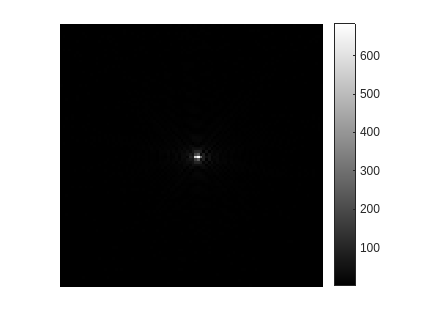

TR=1; % 1 second
TE=50e-03; % 50 ms

% test cartesian kx, ky
[kx,ky] = meshgrid(-rec_size/2:rec_size/2-1,-rec_size/2:rec_size/2-1);

%brainKspace = kspace(M0=M0,T2star=t2star,T1=t1,deltaB=deltaB,timeMap=timeMap,TR=TR,kx=kx,ky=ky);

%brainKspace = kspace(M0,-1,-1,-1,TE,TR,kx,ky);
brainKspace = kspace(M0,t2star,t1,deltaB,timeMap,TR,kx,ky);

figure;
imagesc(abs(brainKspace))
axis image; axis off;
colormap('gray'); colorbar

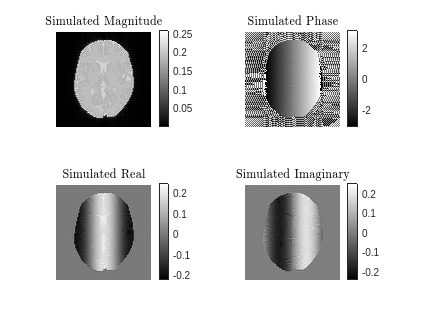


brainIMG=ifft2(fftshift(brainKspace));
figure;
subplot(2,2,1)
imagesc(abs(brainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Magnitude',Interpreter='latex')
subplot(2,2,2)
imagesc(angle(brainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Phase',Interpreter='latex')
subplot(2,2,3)
imagesc(real(brainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Real',Interpreter='latex')
subplot(2,2,4)
imagesc(imag(brainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Imaginary',Interpreter='latex')



mask = (abs(brainIMG)./max(abs(brainIMG),[],'all')) > (1/10);
signalMean = sum(mask.*abs(brainIMG),'all')./sum(mask~=0,'all');
noiseMean = sum((1-mask).*abs(brainIMG),'all')./sum(mask==0,'all');
trueSNR = signalMean/noiseMean

trueSNR = 56.2450

try adding noise!

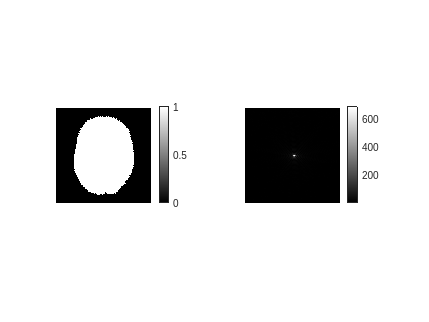

SNR = 10000000000;

mask = (abs(brainIMG)./max(abs(brainIMG),[],'all')) > (1/10);
normalVar = getnoise(brainIMG,SNR);
noiseK = sqrt(normalVar)*(randn(size(brainKspace))+sqrt(-1)*randn(size(brainKspace)));
noisyKspace = noiseK+brainKspace;


figure;
subplot(1,2,1)
imagesc(abs(mask))
axis image; axis off;
colormap('gray'); colorbar
subplot(1,2,2)
imagesc(abs(noisyKspace))
axis image; axis off;
colormap('gray'); colorbar


noisyBrainIMG=ifft2(fftshift(noisyKspace));

signalMean = sum(mask.*abs(noisyBrainIMG),'all')./sum(mask~=0,'all');
noiseMean = sum((1-mask).*abs(noisyBrainIMG),'all')./sum(mask==0,'all');
testSNR = signalMean/noiseMean

testSNR = 56.2450

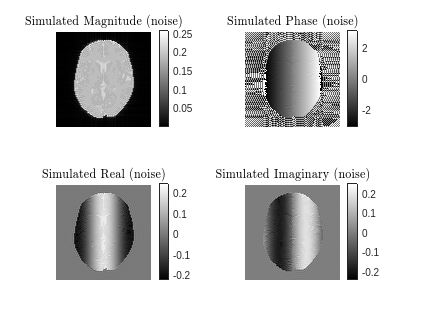



figure;
subplot(2,2,1)
imagesc(abs(noisyBrainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Magnitude (noise)',Interpreter='latex')
subplot(2,2,2)
imagesc(angle(noisyBrainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Phase (noise)',Interpreter='latex')
subplot(2,2,3)
imagesc(real(noisyBrainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Real (noise)',Interpreter='latex')
subplot(2,2,4)
imagesc(imag(noisyBrainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Imaginary (noise)',Interpreter='latex')

get plot of desired v empirical SNRs

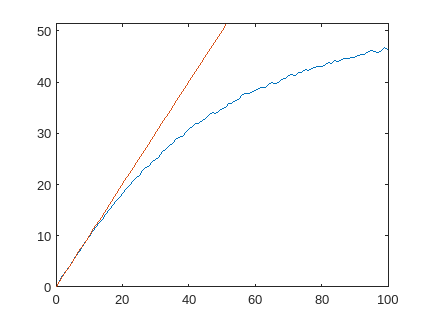

SNRs = [1:100]';
testSNRs = zeros(size(SNRs));
for k=1:length(SNRs)
    normalVar = getnoise(brainIMG,SNRs(k));
    noiseK = sqrt(normalVar)*(randn(size(brainKspace))+sqrt(-1)*randn(size(brainKspace)));
    noisyKspace = noiseK+brainKspace;
    noisyBrainIMG=ifft2(fftshift(noisyKspace));
    signalMean = sum(mask.*abs(noisyBrainIMG),'all')./sum(mask~=0,'all');
    noiseMean = sum((1-mask).*abs(noisyBrainIMG),'all')./sum(mask==0,'all');
    testSNRs(k) = signalMean/noiseMean;
end

figure;
plot(SNRs,testSNRs)
hold on
fplot(@(x) x, [0,max(SNRs)])
hold off
ylim([0 1.1*max(testSNRs)])

test averaging image

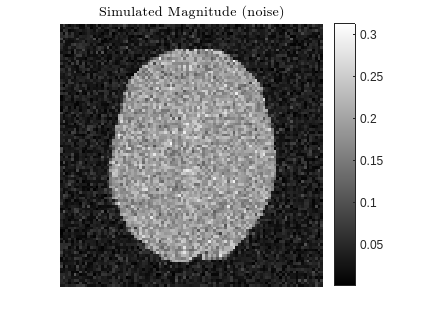

normalVar = getnoise(brainIMG,5);

testIMG = zeros(size(brainIMG));
len=100;
for k=1:len
    noiseK = sqrt(normalVar)*(randn(size(brainKspace))+sqrt(-1)*randn(size(brainKspace)));
    noisyKspace = noiseK+brainKspace;
    noisyBrainIMG=ifft2(fftshift(noisyKspace));
    testIMG = testIMG + noisyBrainIMG;
end
testIMG = testIMG / len;
figure;
imagesc(abs(noisyBrainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Magnitude (noise)',Interpreter='latex')

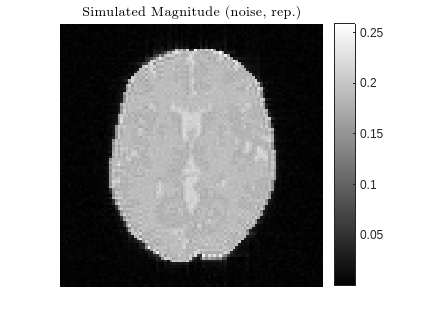

figure;
imagesc(abs(testIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Magnitude (noise, rep.)',Interpreter='latex')

# polar

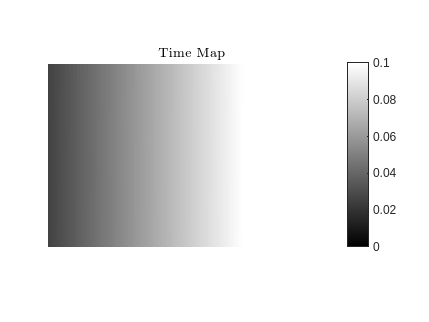

load SpinDenMap.mat
load T1Map.mat
load T2Map.mat

rec_size=96;

M0=SpinDenMap(:,:,40);
t2star=T2Map(:,:,40);
t1=T1Map(:,:,40);
deltaB = repmat(linspace(-2.5,2.5,rec_size)*10e-7,rec_size,1);
deltaB = deltaB + t1./(10^8);

TR=1; % 1 second
TE=50e-03; % 50 ms
gamma=42e-06; % 42 MHz
FOV=240e-03; % FOV in mm

% test polar kx, ky

nsamp = rec_size;
nspokes = ceil(pi/2 * rec_size); % pi/2 * sampling density
% create polar k-space
xr=[-nsamp/2:1:nsamp/2-1]';
angles = linspace(0,180,nspokes+1);
angles(end)=[];
kx=zeros(nsamp,nspokes);
ky=zeros(nsamp,nspokes);
for m=1:nspokes
    kx(:,m) = xr*cosd(angles(m));
    ky(:,m) = xr*sind(angles(m));
end
rampdcf = 1/nspokes + (kx.^2 + ky.^2).^(0.5);

eesp = 0.000720;
deltaT = 1/(2*125*10^3);
extras=0;
TE=50;
TE = TE * 151/96;
timeMap = zeros(nspokes,nsamp);
count = 0;
for row = 1:nspokes
    for col = 1:nsamp
        if mod(row,2)==1
            timeMap(row,col)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        elseif mod(row,2)==0
            timeMap(row,nsamp-col+1)=(row-1)*extras*deltaT+(col-1)*deltaT+(row-1)*eesp;
        end
    end
end
timeMapMsec = timeMap*1000;
init_t = TE - timeMapMsec(floor(nspokes/2)-1,nsamp); % get middle time
timeMap = (timeMap + init_t/1000)';

figure;
imagesc(timeMap,[0,0.1])
axis image; axis off;
colormap('gray'); colorbar;
title('Time Map',Interpreter='latex')

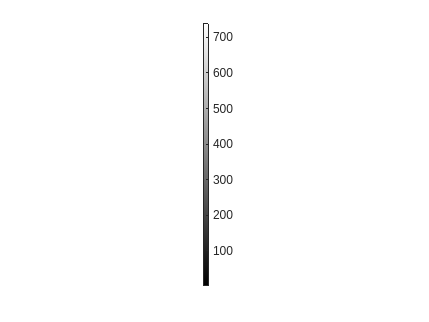

TR=1; % 1 second
TE=50e-03;

polarBrainKspace = kspace(M0,t2star,t1,deltaB,TE,TR,kx,ky);
%polarBrainKspace = kspace(M0,-1,-1,-1,TE,TR,kx,ky);


figure;
imagesc(abs(polarBrainKspace))
axis image; axis off;
colormap('gray'); colorbar

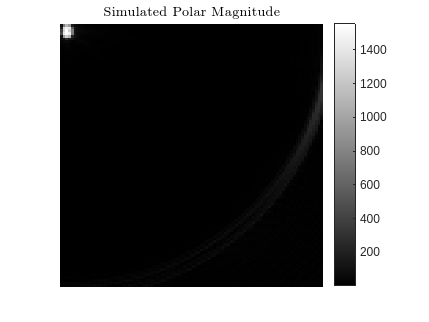

kx = rescale(kx(:),-1*pi,1*pi);
ky = rescale(ky(:),-1*pi,1*pi);
isign = -1; tol = 1e-5; 
ms=4*rec_size; mt=4*rec_size;
opts.modeord = 1; opts.chkbnds = 0;
polarBrain = finufft2d1(kx,ky,polarBrainKspace.*rampdcf,isign,tol,ms,mt,opts);
polarBrain = rot90(transpose(reshape(polarBrain,ms,mt)),2);
polarBrain = (1/nsamp/nspokes)*polarBrain(1:rec_size,1:rec_size); % or (1/rec_size/rec_size)?


figure;
imagesc(abs(polarBrain))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Polar Magnitude',Interpreter='latex')

%exportgraphics(gcf,'figures/polar-mag.png','Resolution',600)

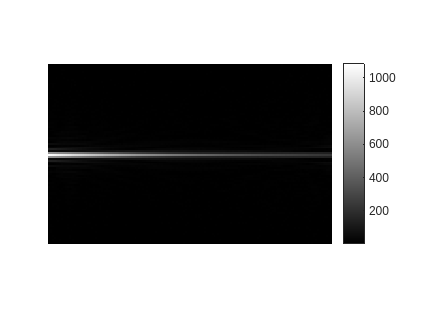

% use mask from cartesian form
% and variance from cartesian
noisePolarK = sqrt(normalVar)*(randn(size(polarBrainKspace))+sqrt(-1)*randn(size(polarBrainKspace)));
noisyPolarKspace = noisePolarK+polarBrainKspace;


figure;
imagesc(abs(noisyPolarKspace))
axis image; axis off;
colormap('gray'); colorbar


kx = rescale(kx(:),-1*pi,1*pi);
ky = rescale(ky(:),-1*pi,1*pi);
isign = -1; tol = 1e-5; 
ms=4*rec_size; mt=4*rec_size;
opts.modeord = 1; opts.chkbnds = 0;
noisyPolarBrainIMG = finufft2d1(kx,ky,noisyPolarKspace.*rampdcf,isign,tol,ms,mt,opts);
noisyPolarBrainIMG = rot90(transpose(reshape(noisyPolarBrainIMG,ms,mt)),2);
noisyPolarBrainIMG = (1/nsamp/nspokes)*noisyPolarBrainIMG(1:rec_size,1:rec_size); % or (1/rec_size/rec_size)?


signalMean = sum(mask.*abs(noisyPolarBrainIMG),'all')./sum(mask~=0,'all');
noiseMean = sum((1-mask).*abs(noisyPolarBrainIMG),'all')./sum(mask==0,'all');
testSNR = (signalMean-noiseMean)/noiseMean

testSNR = 0.6478

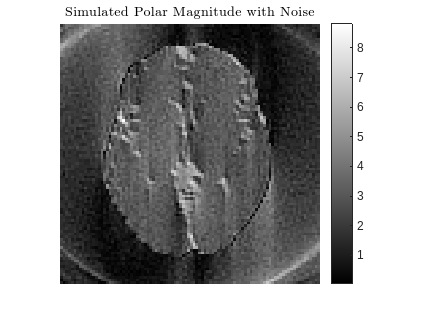


figure;
imagesc(abs(noisyPolarBrainIMG))
axis image; axis off;
colormap('gray'); colorbar
title('Simulated Polar Magnitude with Noise',Interpreter='latex')